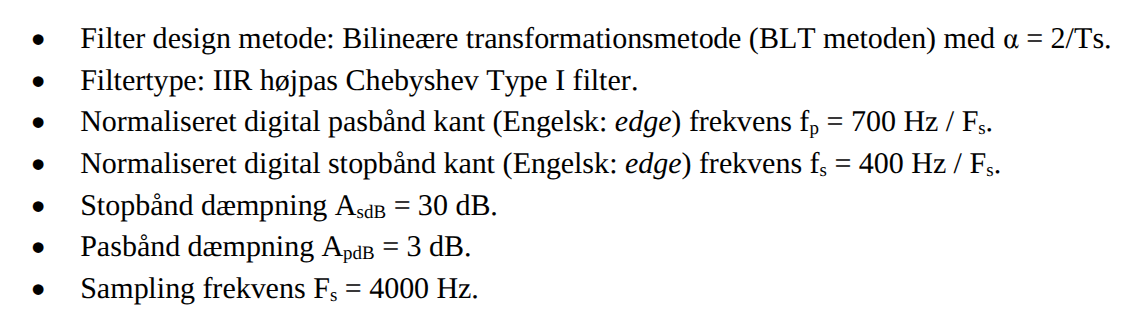

f_p = 700; f_s = 400; A_sdB = 30; A_pdB = 3; F_s = 4e3;

omega_p = (2*pi*f_p)/F_s; omega_s = (2*pi*f_s)/F_s;

Omega_p = 2*F_s*tan(omega_p/2)

Omega_p = 4.9024e+03

Omega_s = 2*F_s*tan(omega_s/2)

Omega_s = 2.5994e+03

nu = Omega_p/Omega_s;
n_value(A_sdB, A_pdB, nu)

e = 1.000000
n = 6.000000

Dvs. n = 6

b_p = 0.0313; a_p = [1 0.5707 1.6628 0.6906 0.6991 0.1634 0.0442];

H_proto = tf(b_p, a_p)


H_proto =
 
                                    0.0313
  --------------------------------------------------------------------------
  s^6 + 0.5707 s^5 + 1.663 s^4 + 0.6906 s^3 + 0.6991 s^2 + 0.1634 s + 0.0442
 
Continuous-time transfer function.



$$s\longrightarrow \frac{\Omega_p }{s}$$


[bt, at] = lp2hp(b_p, a_p, Omega_p);
H_hp = tf(bt, at)


H_hp =
 
      0.7081 s^6 + 3.836e-12 s^5 + 7.632e-10 s^4 + 3.162e-07 s^3 + 3.434 s^2 + 4209 s
  ---------------------------------------------------------------------------------------
  s^6 + 1.812e04 s^5 + 3.801e08 s^4 + 1.841e12 s^3 + 2.173e16 s^2 + 3.656e19 s + 3.141e23
 
Continuous-time transfer function.


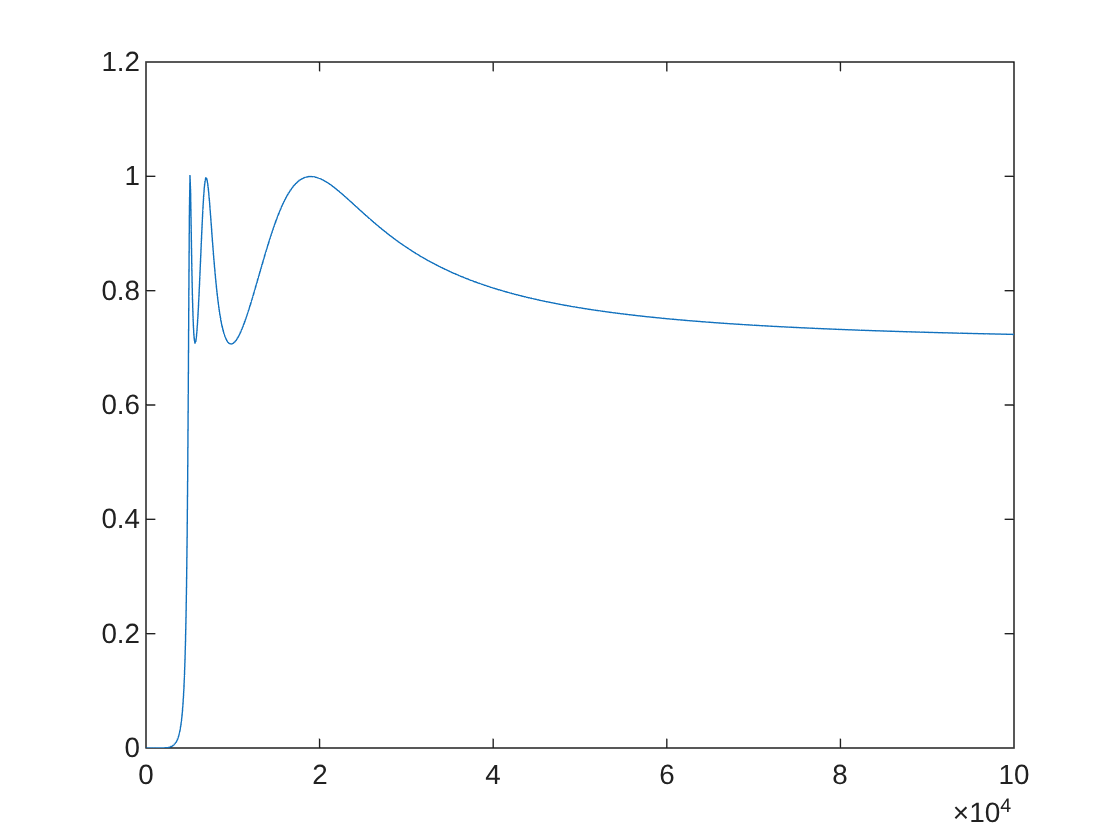

[h, w] = freqs(bt, at, 1024);
figure();
plot(w, abs(h));

[bd, ad] = bilinear(bt, at, F_s);

H_z = tf(bd, ad, 1/F_s, 'Variable', 'z^-1')


H_z =
 
  0.03468 - 0.2081 z^-1 + 0.5202 z^-2 - 0.6936 z^-3 + 0.5202 z^-4 - 0.2081 z^-5 + 0.03468 z^-6
  --------------------------------------------------------------------------------------------
      1 - 0.2291 z^-1 + 1.364 z^-2 + 0.3183 z^-3 + 0.7643 z^-4 + 0.2213 z^-5 + 0.3167 z^-6
 
Sample time: 0.00025 seconds
Discrete-time transfer function.


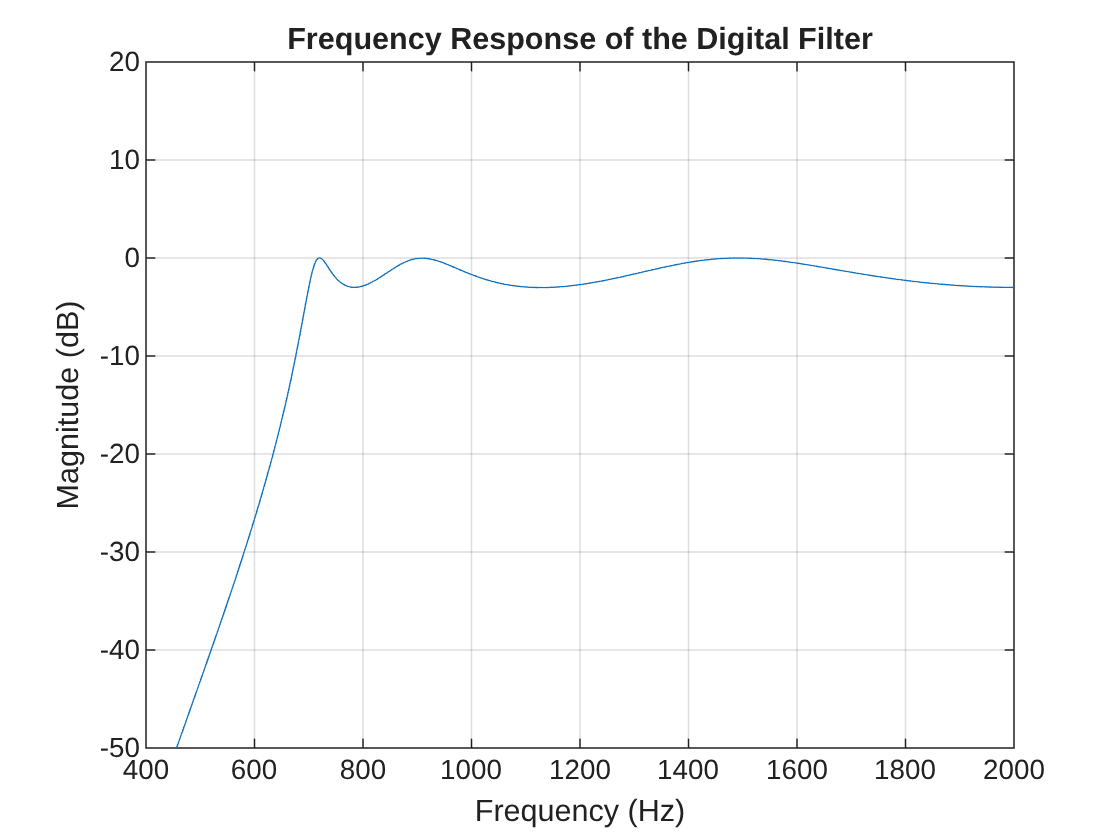

[h, f] = freqz(bd, ad, 1024, F_s);

figure();
plot(f, 20*log10(abs(h)));
ylim([-50 20]);
title('Frequency Response of the Digital Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

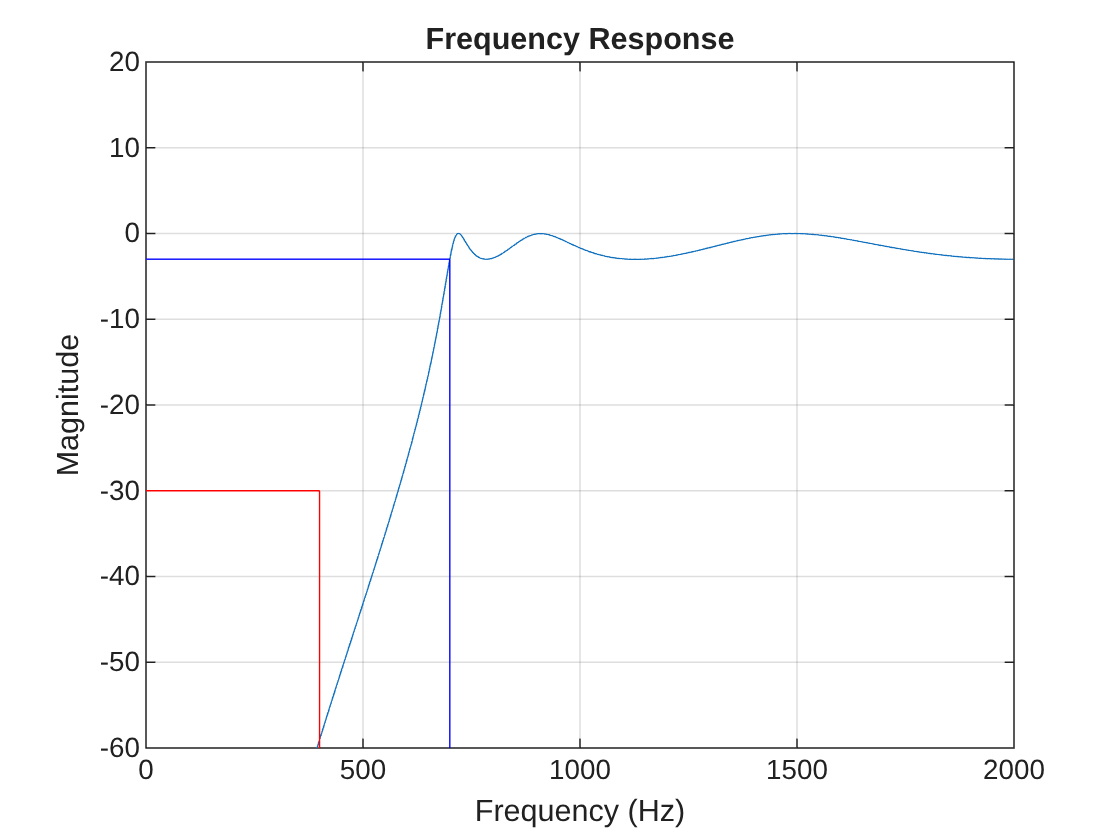

    figure();
    plot(f, 20*log10(abs(h)))
    ylim([-60 20]);
    line([f_s f_s],[-A_sdB -60], 'Color','r');
    line([f_p f_p], [-A_pdB -60], 'Color', 'b');
    line([0 f_s], [-A_sdB -A_sdB], 'Color', 'r');
    line([0 f_p], [-A_pdB -A_pdB], 'Color', 'b');

    %labels
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title('Frequency Response');
    grid on;

Opg.4

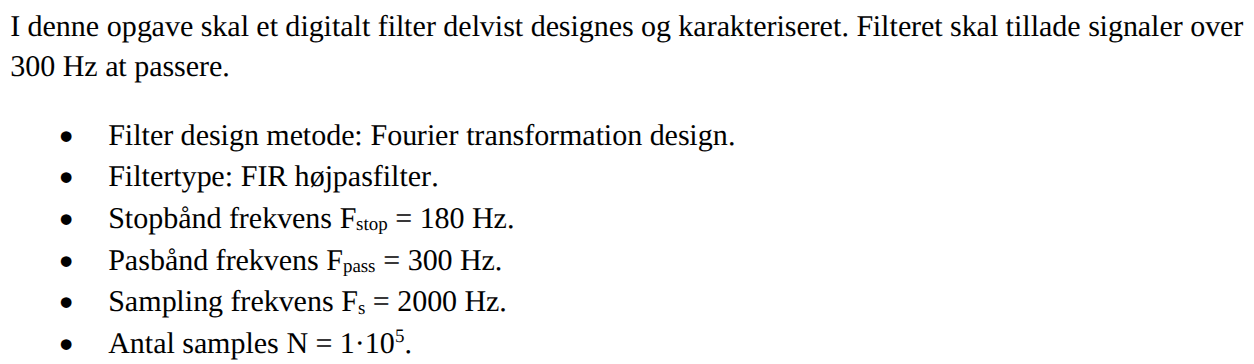

clear; clc;
format long;
f_s = 180; f_p = 300; F_s = 2e3; N = 10^5;

F_c = (f_s+f_p)/2;
omega_c = (2*pi*F_c)/F_s

omega_c =    0.753982236861550


F_sharpness = abs(f_s-f_p)/F_s;

N_taps = 0.9/F_sharpness

N_taps =   15.000000000000002


syms M K
M_value = double(solve(N_taps == M + 1, M))

M_value =     14


K_value = double(solve(N_taps == 2*K + 1, K))

K_value =      7


n = -K_value:K_value;
h = -(omega_c/pi)*sinc((n.*omega_c)/pi)

h =    0.038393989409763   0.052111957163206   0.037419571351546  -0.009973701827725  -0.081753994203688  -0.158840887167192  -0.217898111375604  -0.240000000000000  -0.217898111375604  -0.158840887167192  -0.081753994203688  -0.009973701827725   0.037419571351546   0.052111957163206   0.038393989409763



tf(h, 1, 1/F_s, 'Variable', 'z^-1')


ans =
 
  0.03839 + 0.05211 z^-1 + 0.03742 z^-2 - 0.009974 z^-3 - 0.08175 z^-4 - 0.1588 z^-5 - 0.2179 z^-6 - 0.24 z^-7 - 0.2179 z^-8 - 0.1588 z^-9 - 0.08175 z^-10 - 0.009974 z^-11 + 0.03742 z^-12 + 0.05211 z^-13 + 0.03839 z^-14
 
Sample time: 0.0005 seconds
Discrete-time transfer function.


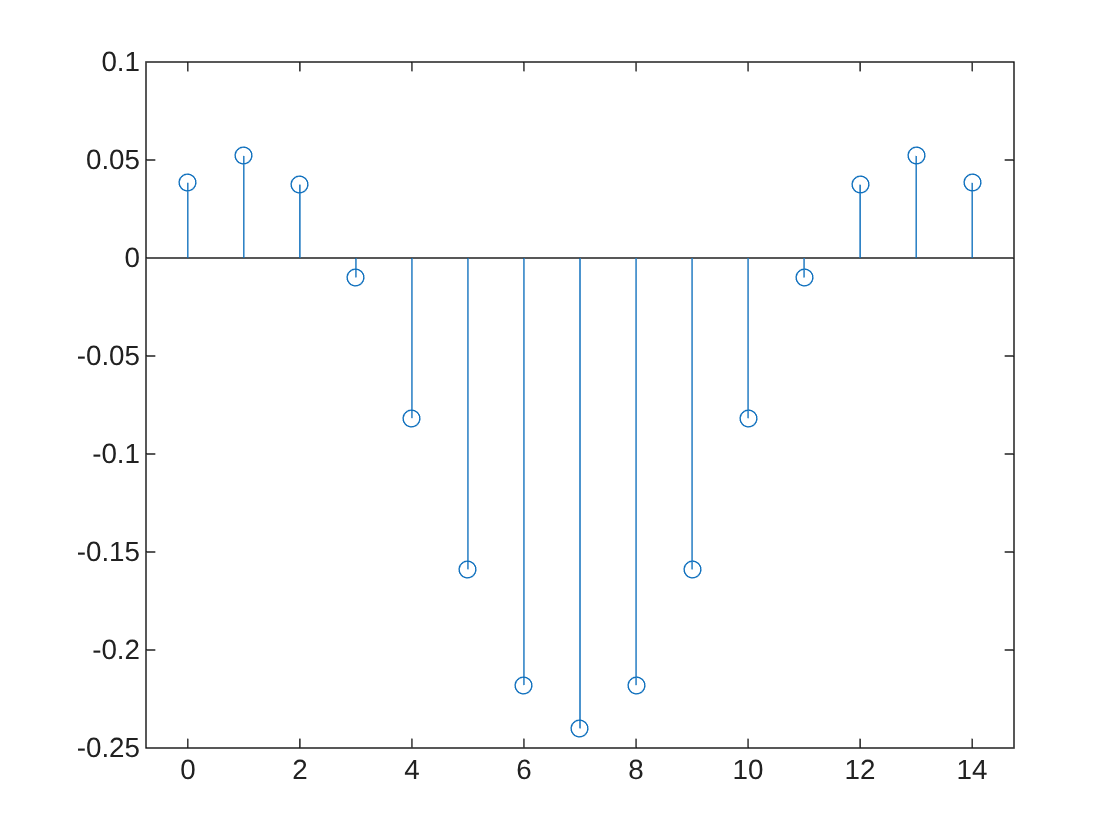

stem(0:M_value, h)%????

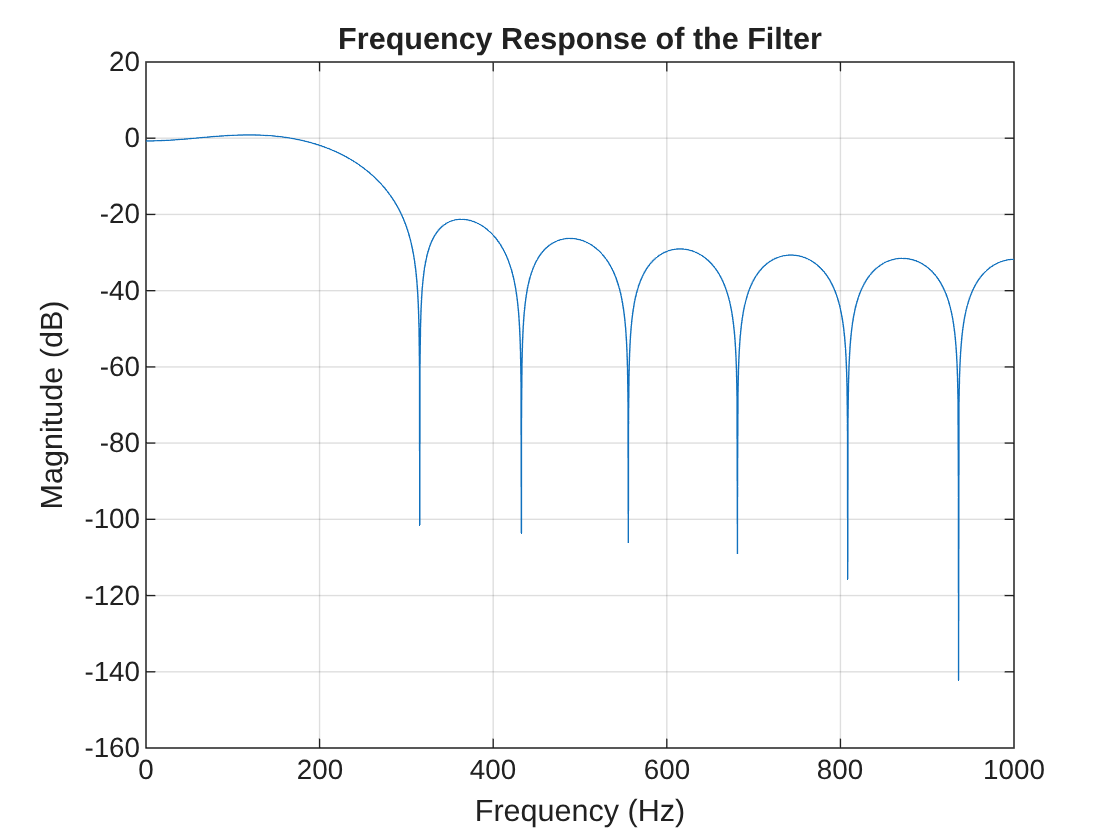


[H, f] = freqz(h, 1, N, F_s);

figure();
plot(f, 20*log10(abs(H)));
% Display the frequency response of the filter
title('Frequency Response of the Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;